## UI Prototype with User Input

clc; clear; clear vars;

%% Using the inputs from the user, start calculating different things
% Plot of Eo(rho)-rho*R
% Plot of the optimisation process
% Optimal rho value
% Max exponent
% Error probability Pe = 2^-n*E(R)

user_inputs = getUserInputUI();
N = user_inputs.N;
SNR = user_inputs.SNR;
M = user_inputs.M;
R = user_inputs.R;
tol = user_inputs.tol;

[nodes, weights] = GaussHermite_Locations_Weights(N);

d = 2;

%% Generate and Normalize PAM Constellation
% Create a PAM constellation with M symbols and spacing d.
X = generatePAMConstellation(M, d);
% Normalize the constellation so that its average energy is 1.
X = X / sqrt(mean(X.^2));

%% Initialize the Probability Distribution for Constellation Symbols
% Create a column vector where each symbol has equal probability (1/M).
Q = repmat(1/M, 1, M);
Q = Q';

% Gaussian expression
G = @(z) (1/pi) * exp(-abs(z).^2);

%% Create Required Matrices for Computation
pi_matrix = createPiMatrix(M, N, weights);
z_matrix = createComplexNodesMatrix(nodes);
g_matrix = createGMatrix(X, z_matrix, SNR, G);

userChoice = getUserOption();
fprintf('User selected: %s\n', userChoice);

User selected: Optimize


Running optimization...


Approx. max of G(rho) is 0.0684 at rho = 0.5322


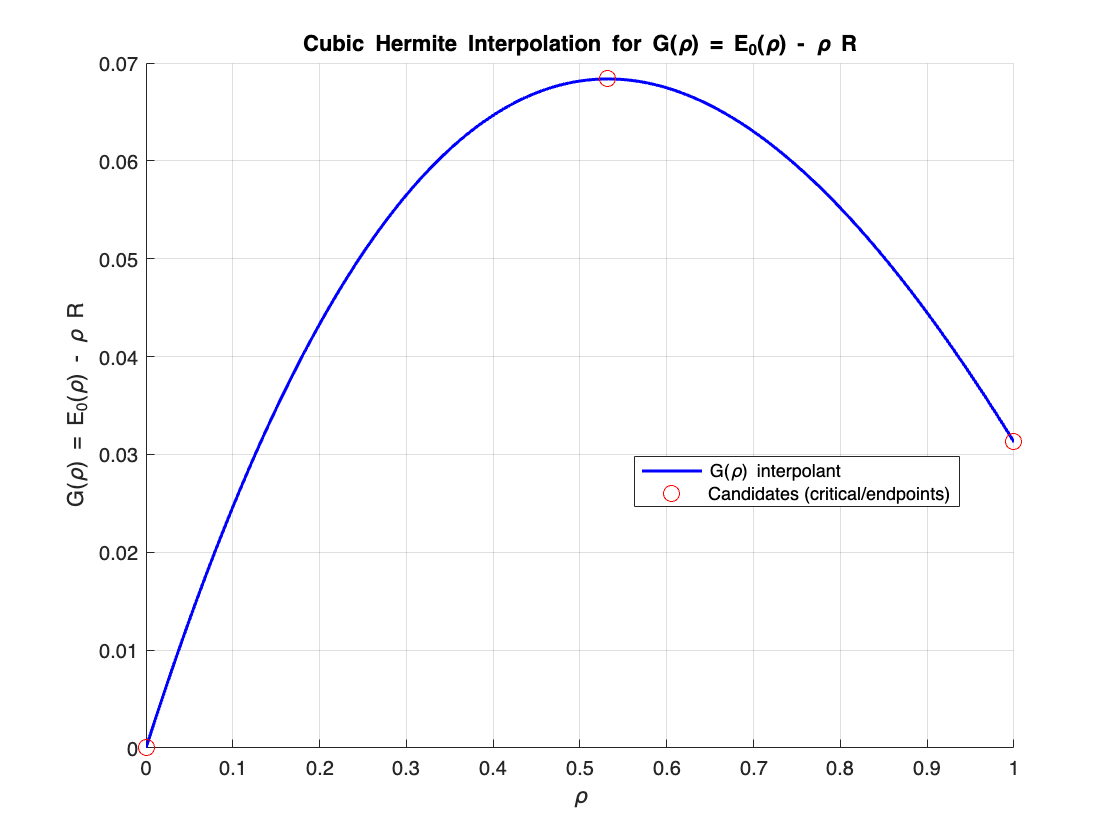

Error using optimizationNewton
Too many input arguments.


switch userChoice
    case 'Optimize'
        % Display start of optimization
        disp('Running optimization...');

        %% Initial Guess for Optimization
        E00 = computeEoForRhoExponential(0, Q, pi_matrix, g_matrix);   % E0 at rho=0
        E01 = computeEoForRhoExponential(1, Q, pi_matrix, g_matrix);   % E0 at rho=1
        E0P0 = computeFirstDerivativeE0(Q, pi_matrix, g_matrix, 0);   % Derivative at rho=0
        E0P1 = computeFirstDerivativeE0(Q, pi_matrix, g_matrix, 1);   % Derivative at rho=1

        % Hermite interpolation for initial guess
        rho_star = demoHermiteInterpolation(E00, E0P0, E01, E0P1, R);

        %% Newton's Method for Optimal rho
        tic;  % Start overall timer

        % Boundary conditions to avoid unnecessary optimization
        if R > E0P0
            rho_opt = 0;
            E0_max = E00 - rho_opt * R;
        elseif R < E0P1
            rho_opt = 1;
            E0_max = E01 - rho_opt * R;
        else
            % Newton's method for intermediate values
            [rho_opt, E0_max] = optimizationNewton(Q, pi_matrix, g_matrix, R, tol, rho_star);
        end

        %% Display Results
        fprintf('Optimal rho: %.6f\n', rho_opt);
        fprintf('Maximum E0: %.6f\n', E0_max);
        fprintf('Optimization Time: %.2f ms\n', toc * 1000);

    case 'Plot'
        % Call your plotting routine
        disp('Generating plot...');
    case 'Show'
        % Call your show routine
        disp('Showing results...');
    otherwise
        disp('No valid option selected.');
end